Q1.DTFT

a] Write a program to evaluate DTFT which can be expressed as a rational function in e−jw. What is the expression for the DTFT to be evaluated? What is the kind of symmetry exhibited by the magnitude and phase spectrum?

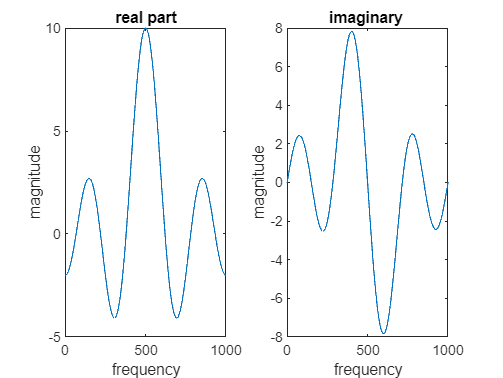

%x=input("enter the sequence : ");
x=[1 2 3 4];
n=1:length(x);
X=0;
w=linspace(-pi,pi,1000);
for i=1:length(x)
    X=X+x(i)*exp(-1i*w*(i-1));
end
figure();
subplot(1,2,1);
plot(real(X));
title('real part');
xlabel('frequency');
ylabel('magnitude');
subplot(1,2,2);
plot(imag(X));
title('imaginary ');
xlabel('frequency');
ylabel('magnitude');

b] modyfing above question 

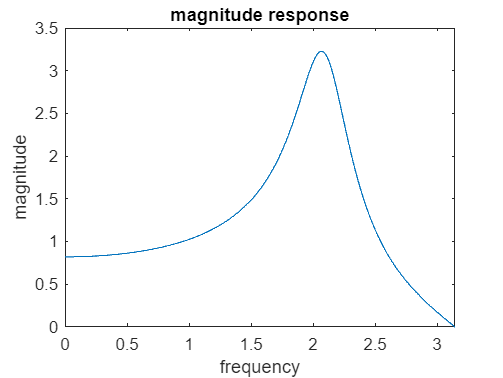

w=linspace(0,pi,1000);
X=(1+exp(-1i*w))./(1+0.8*exp(-1i*w)+0.64*exp(-1i*2*w));
figure();
plot(w,abs(X));
title('magnitude response');
xlabel('frequency');
ylabel('magnitude');

c]

n=[0,15]

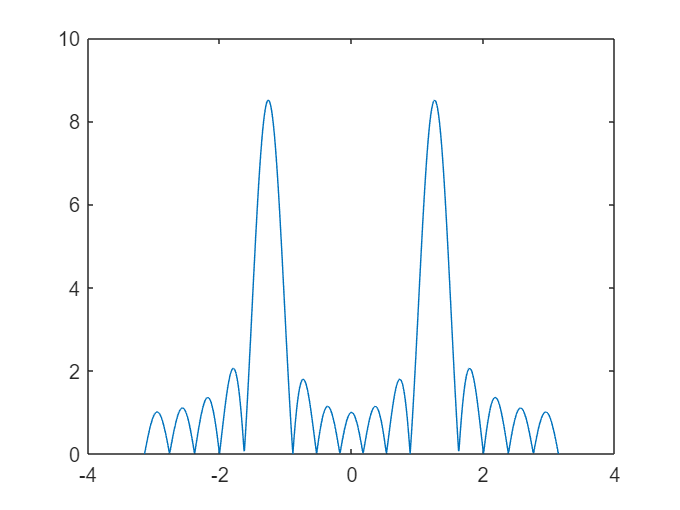

n=0:15;
x=cos(0.4*pi*n);
X=0;
w=linspace(-pi,pi,1000);

for i=1:length(x)
    X=X+x(i)*exp(-1i*w*(i-1));
end
figure();
plot(w,abs(X));

n=[0,63]

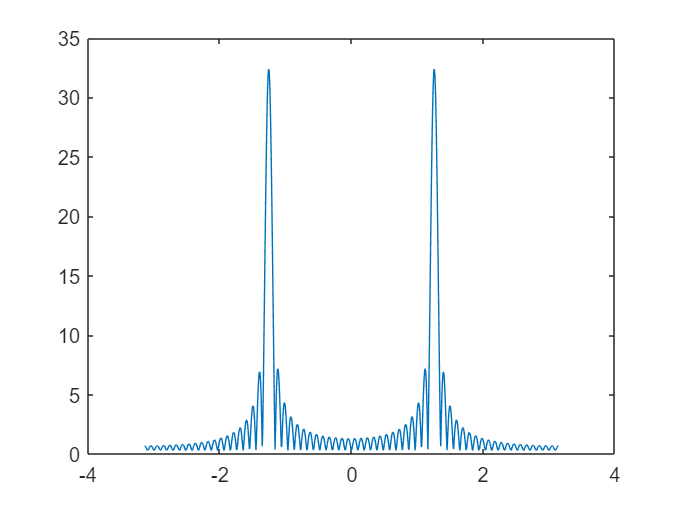

n=0:63;
x=cos(0.4*pi*n);
X=0;
w=linspace(-pi,pi,1000);

for i=1:length(x)
    X=X+x(i)*exp(-1i*w*(i-1));
end
figure();
plot(w,abs(X));

d]

M=5

M = 5

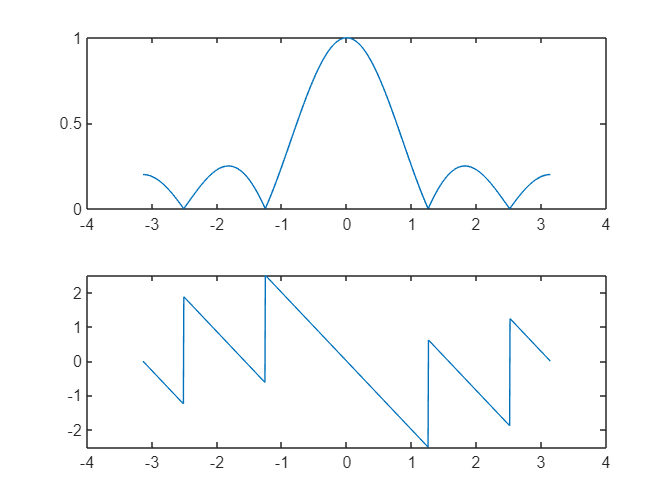

f=(1/M)*ones(1,M);
w=linspace(-pi,pi,1000);
h=freqz(f,1,w);
figure();
subplot(2,1,1);
plot(w,abs(h));
subplot(2,1,2);
plot(w,angle(h));

2.

a]

x=[1 2 3 4];
X=dft(x)

X =   10.0000 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 0.0000i
  -2.0000 - 2.0000i


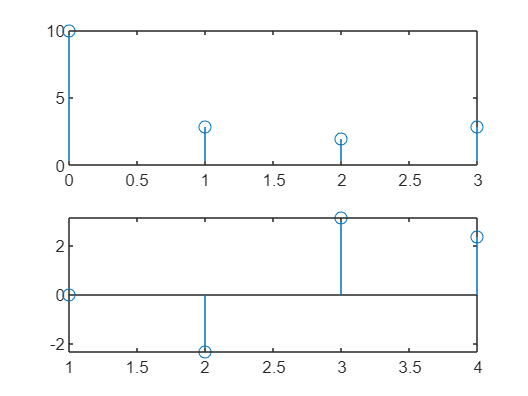

figure();
subplot(2,1,1)
stem(0:length(x)-1,abs(X'));
subplot(2,1,2)
stem(angle(X'));


fft(x)'

ans =   10.0000 + 0.0000i
  -2.0000 - 2.0000i
  -2.0000 + 0.0000i
  -2.0000 + 2.0000i


b]

%x=[1 2 3 4];

ans =   10.0000 + 0.0000i
   2.1574 + 7.8294i
  -4.0129 + 1.0846i
   1.4011 - 2.0989i


%n=1:length(x);
%X=0;
%w=0:length(x)-1;
%w=w./(2*pi/(length(x)));
%for i=1:length(x)
%    X=X+x(i)*exp(-j*w*(i-1));
%end
%X'

function X=dft(x)
    %Linear transformation using W matrix for an N point DFT
    N2=length(x);
    X=zeros(N2,1);
    %the twiddle factor
    m=exp(-1i*2*pi/N2);
    W=zeros(N2,N2);
    tic
    %creating the W matrix
    for k=0:N2-1
     for n=0:N2-1
     W(k+1,n+1)=m.^(k*n);
     end
    end
    X=W*x';
end